# MIP Calculator

Code explained [here](https://onedrive.live.com/view.aspx?resid=6734D084BA63FB2%21487&id=documents&wd=target%28Doublepass%20%28xDBL%20xGTS%5C%29.one%7CA0379185-A565-4240-A5C4-68F4755BFB4B%2FMembrane%20Phase%20Object%20Calculations%7C9B3E84CD-6EF2-48BF-B756-7DEEDF289206%2F%29 onenote:https://d.docs.live.net/06734d084ba63fb2/Documents/Research/Doublepass%20(xDBL%20xGTS).one#Membrane%20Phase%20Object%20Calculations&section-id={A0379185-A565-4240-A5C4-68F4755BFB4B}&page-id={9B3E84CD-6EF2-48BF-B756-7DEEDF289206}&end)

From Riemer:

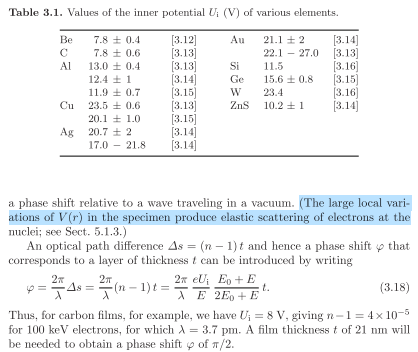

Where E is the electron energy, E_o the electron rest energy

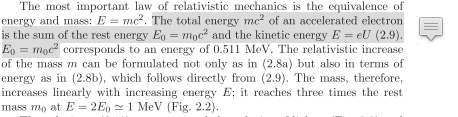

From hyperphysics

A dedicated paper claims:

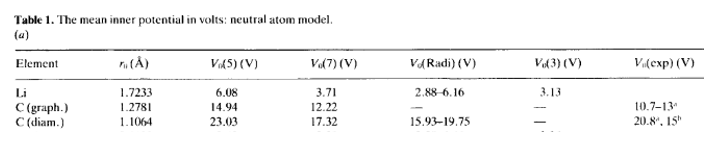

#### Verification

Wavelength verfified with hyperphysics comparison at 3 and 10 keV

Phase verified with Reimer example:

## Simple analysis

addpath('C:\Users\johns\Documents\Github\QEM-MATLAB');
load ImpVariables.mat;
KE = 1*c.kilo;
lambda = electronWavelength(KE)


## Phase Object Strength

thickness = [0.355] * c.nano; % film thickness in nm
innerPot = [13.24]; %eV
deltaPhase = 2*pi/lambda * (innerPot/KE) *...
    ((c.eRestMass_eV+KE)/(2*c.eRestMass_eV+KE)) * thickness
deltaPhasePiOver2 = deltaPhase*2/pi


## Diffraction

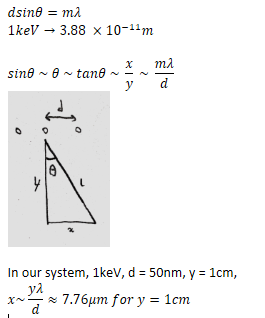

clf
%hold on
d =  [0.246]*c.nano;
y = 10*c.milli;

KE = [0.5:0.2:10]*c.kilo;
lambda = electronWavelength(KE);

pc = 	1.0e+05 *

    0.2261    0.2676    0.3034    0.3355    0.3647    0.3918    0.4172    0.4411    0.4637    0.4854    0.5061    0.5260    0.5452    0.5637    0.5817    0.5991    0.6160    0.6325    0.6486    0.6643    0.6796    0.6947    0.7094    0.7238    0.7379    0.7517    0.7654    0.7788    0.7919    0.8049    0.8176    0.8302    0.8426    0.8548    0.8668    0.8787    0.8904    0.9020    0.9134    0.9247    0.9359    0.9469    0.9579    0.9687    0.9793    0.9899    1.0004    1.0107


lambda = 	1.0e+-10 *

    0.5483    0.4634    0.4086    0.3696    0.3399    0.3164    0.2972    0.2811    0.2674    0.2554    0.2450    0.2357    0.2274    0.2199    0.2131    0.2069    0.2013    0.1960    0.1912    0.1866    0.1824    0.1785    0.1748    0.1713    0.1680    0.1649    0.1620    0.1592    0.1566    0.1540    0.1516    0.1493    0.1471    0.1450    0.1430    0.1411    0.1392    0.1375    0.1357    0.1341    0.1325    0.1309    0.1294    0.1280    0.1266    0.1252    0.1239    0.1227


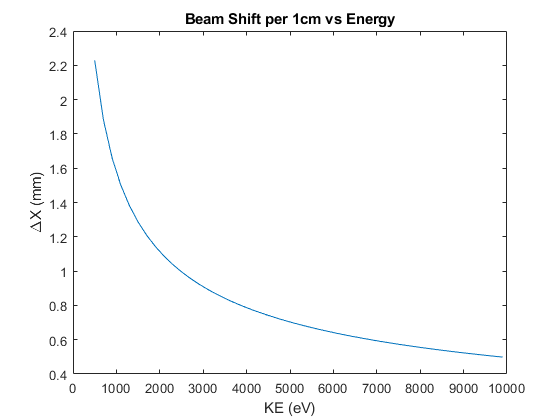

deltaX = y*lambda/d;
plot(KE, deltaX/c.milli); xlabel("KE (eV)"); ylabel("{\Delta}X (mm)")
title("Beam Shift per 1cm vs Energy")

theta = asin(lambda/d)*180/(pi);
